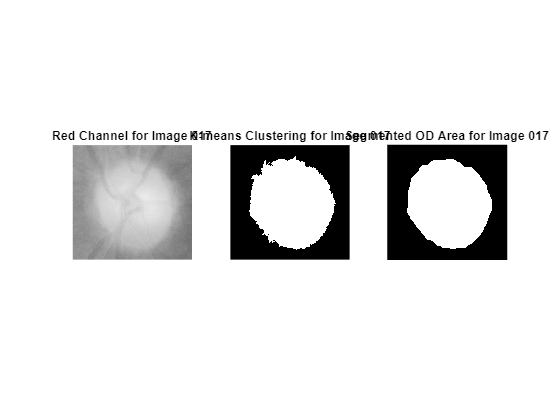

Segmented OD area image saved as segmentedOD_017.png


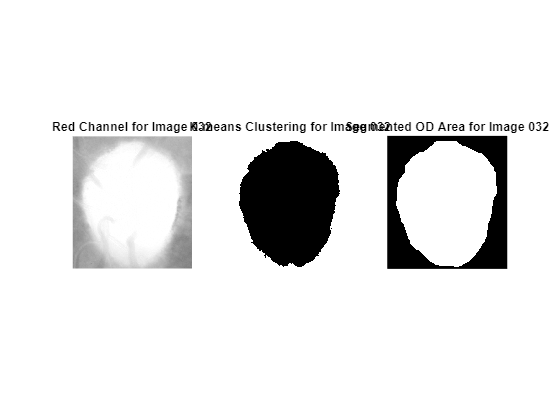

Segmented OD area image saved as segmentedOD_032.png


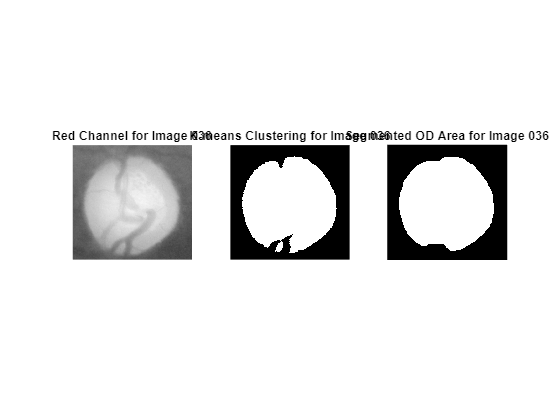

Segmented OD area image saved as segmentedOD_036.png


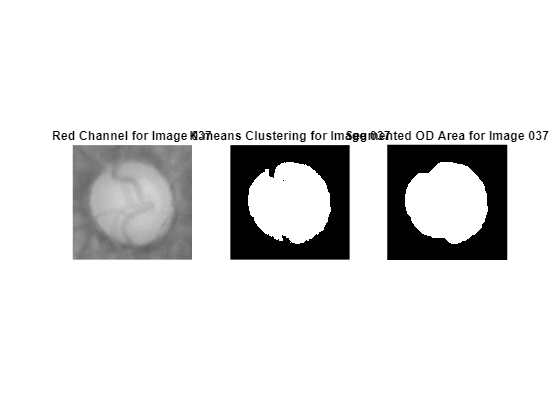

Segmented OD area image saved as segmentedOD_037.png


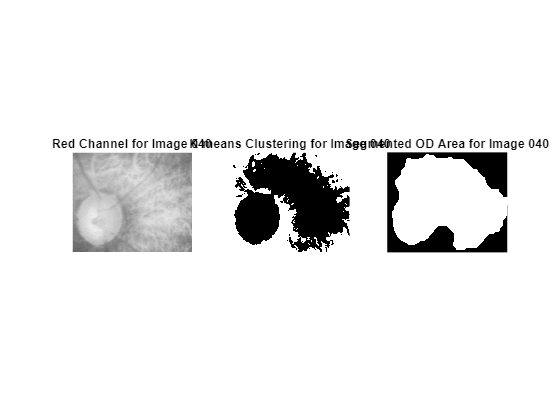

Segmented OD area image saved as segmentedOD_040.png


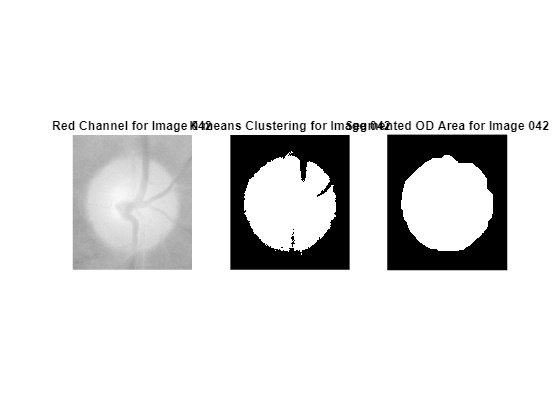

Segmented OD area image saved as segmentedOD_042.png


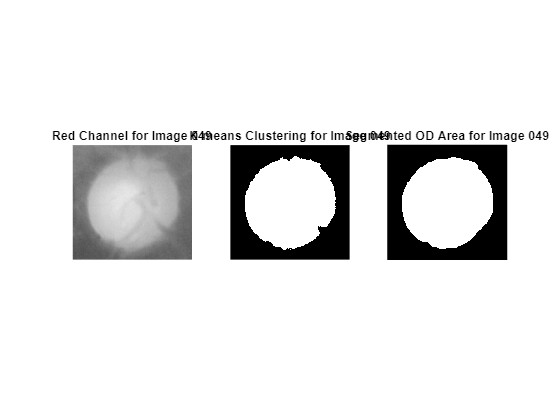

Segmented OD area image saved as segmentedOD_049.png


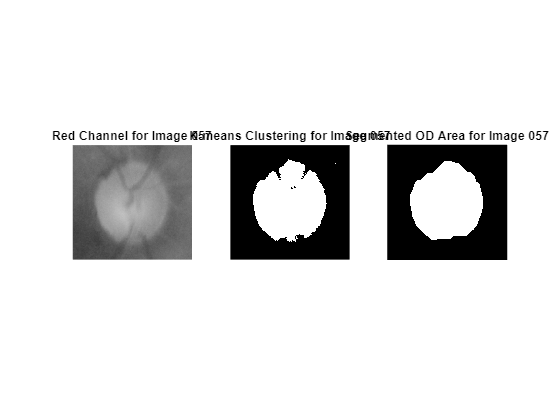

Segmented OD area image saved as segmentedOD_057.png


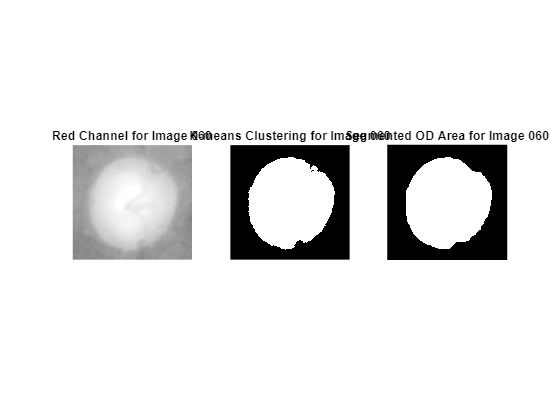

Segmented OD area image saved as segmentedOD_060.png


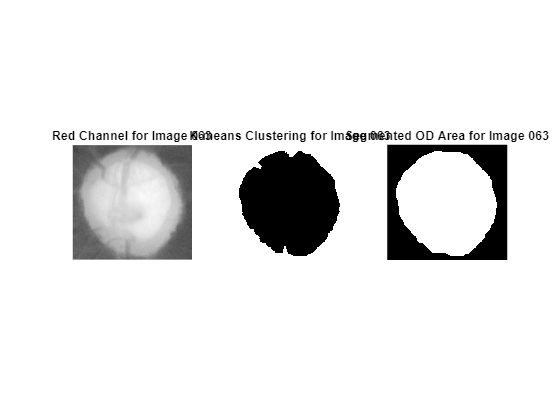

Segmented OD area image saved as segmentedOD_063.png


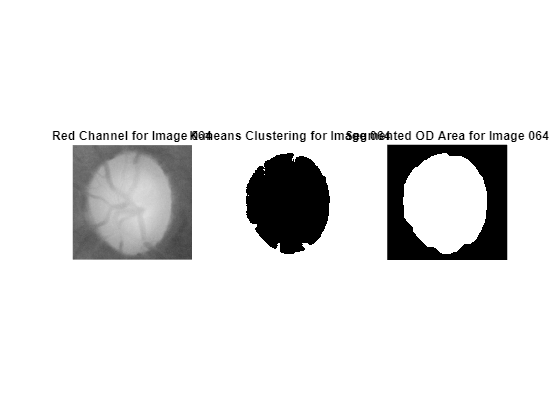

Segmented OD area image saved as segmentedOD_064.png


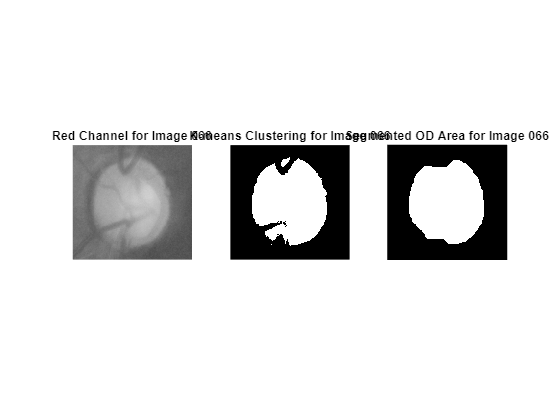

Segmented OD area image saved as segmentedOD_066.png


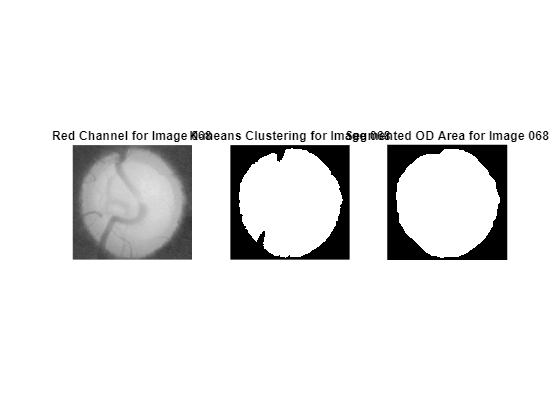

Segmented OD area image saved as segmentedOD_068.png


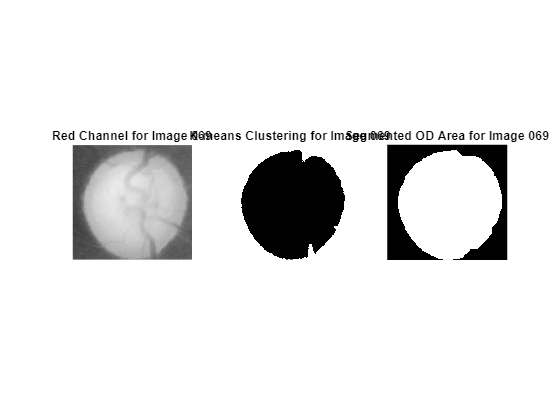

Segmented OD area image saved as segmentedOD_069.png


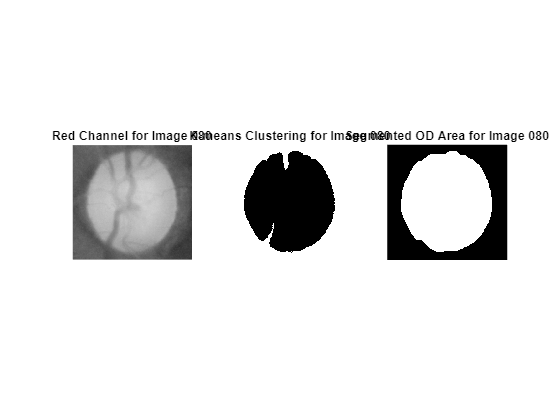

Segmented OD area image saved as segmentedOD_080.png


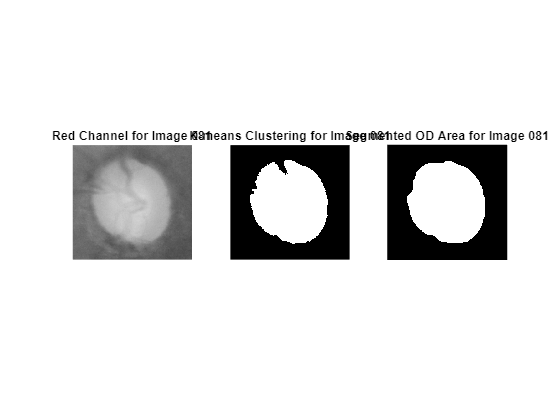

Segmented OD area image saved as segmentedOD_081.png


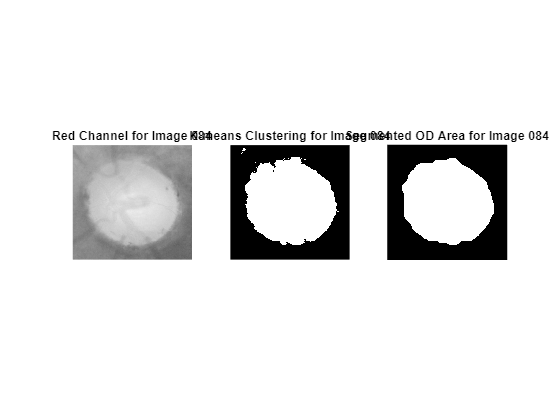

Segmented OD area image saved as segmentedOD_084.png


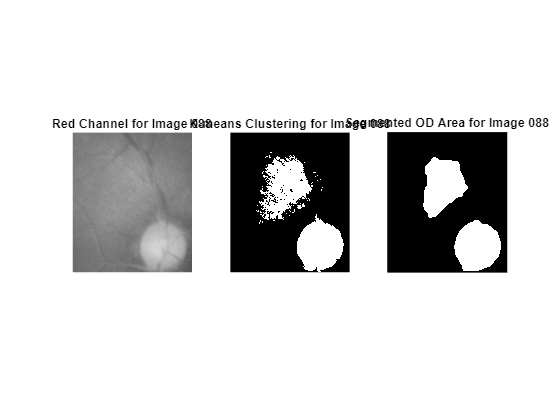

Segmented OD area image saved as segmentedOD_088.png


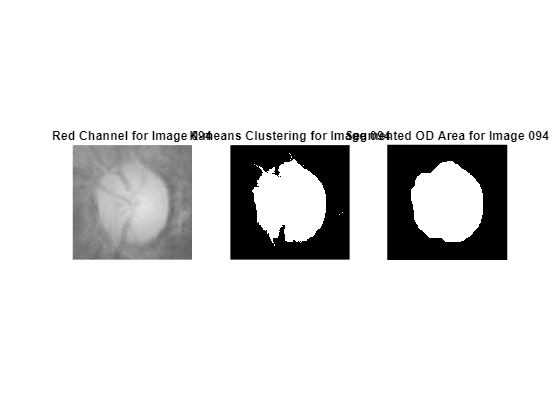

Segmented OD area image saved as segmentedOD_094.png


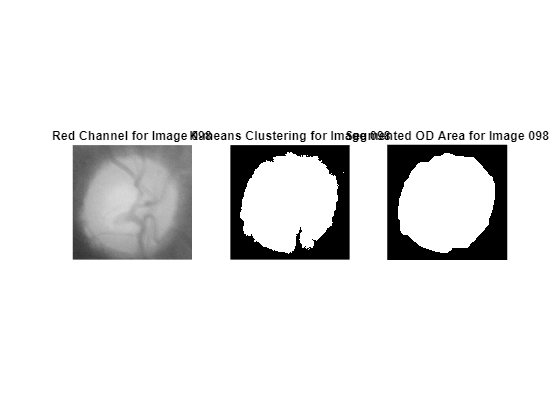

Segmented OD area image saved as segmentedOD_098.png


% List of specific image numbers
imageNumbers = [17, 32, 36, 37, 40, 42, 49, 57, 60, 63, 64, 66, 68, 69, 80, 81, 84, 88, 94, 98];

% Base directory for the cropped OD images
baseDirCroppedImages = 'F:\Semester 6\Pengolahan Citra Biomedika\Tubes\OverlayOutput\RoI\';

% Output directory for the processed images
outputDir = 'F:\Semester 6\Pengolahan Citra Biomedika\Tubes\OverlayOutput\Segmentasi';
if ~exist(outputDir, 'dir')
    mkdir(outputDir);
end

for i = 1:length(imageNumbers)
    % Get the current image number
    imageNumber = imageNumbers(i);
    
    % Generate filename for the cropped OD image
    inputImageFile = fullfile(baseDirCroppedImages, sprintf('RoI_%03d.png', imageNumber));
    
    % Check if the file exists
    if isfile(inputImageFile)
        % Read the image
        img = imread(inputImageFile);
        
        % Convert the image to grayscale by extracting the red channel
        redChannel = img(:,:,1);
        
        % Reshape the image into a 2D array of pixels
        pixelValues = double(redChannel(:));
        
        % Number of clusters for K-means
        numClusters = 2;
        
        % Perform K-means clustering
        [idx, clusterCenters] = kmeans(pixelValues, numClusters, 'MaxIter', 1000);
        
        % Reshape the clustered labels back to the shape of the original image
        clusteredImg = reshape(idx, size(redChannel));
        
        % Identify the cluster that corresponds to the OD
        [~, odCluster] = max(clusterCenters);
        
        % Create a binary mask for the OD
        binaryOD = clusteredImg == odCluster;
        
        % Fill any holes in the binary image to ensure a solid region
        binaryOD = imfill(binaryOD, 'holes');
        
        % Apply morphological operations to clean up the binary image
        binaryOD = imopen(binaryOD, strel('disk', 20));
        binaryOD = imclose(binaryOD, strel('disk', 70));
        
        % Save the binary image highlighting the OD area
        outputFileName = fullfile(outputDir, sprintf('segmentedOD_%03d.png', imageNumber));
        imwrite(binaryOD, outputFileName);
        
        % Debug: Display the original and processed images
        figure;
        subplot(1, 3, 1);
        imshow(redChannel);
        title(sprintf('Red Channel for Image %03d', imageNumber));
        
        subplot(1, 3, 2);
        imshow(clusteredImg, []);
        title(sprintf('K-means Clustering for Image %03d', imageNumber));
        
        subplot(1, 3, 3);
        imshow(binaryOD);
        title(sprintf('Segmented OD Area for Image %03d', imageNumber));
        
        % Debug: Print success message for saving processed binary image
        fprintf('Segmented OD area image saved as segmentedOD_%03d.png\n', imageNumber);
    else
        fprintf('File not found for image number: %03d\n', imageNumber);
    end
end